km = 0.0077 %N.m amp

km = 0.0077

ke = 0.0077 %N.m amp

ke = 0.0077

mp = 0.106  %kg

mp = 0.1060

mc = 0.526  %kg

mc = 0.5260

lp = 0.168  %m 

lp = 0.1680

Ra = 2.6    %ohms 

Ra = 2.6000

rg = 0.0064 %m 

rg = 0.0064

kg = 3.7    %kg

kg = 3.7000

g  = 9.8     %m/s2

g = 9.8000



A = [0 1 0 0 ; 0 K -mp*g/mc 0 ; 0 0 0 1 ; 0  -K/lp g/lp 0]
B = [0 ; (kg*km)/(mc*rg*Ra) ; 0 ; -(kg*km)/(rg*Ra*mc*lp)]
C = [1 0 0 0 ; 0 0 1 0]

A =          0    1.0000         0         0
         0         0   -1.9749         0
         0         0         0    1.0000
         0         0   58.3333         0


B =          0
    1.9011
         0
   -0.3194


C =      1     0     0     0
     0     0     1     0


rank(obsv(A, C))

ans = 4

rank(ctrb(A, B))

ans = 4

eig(A)

ans =          0
         0
    7.6376
   -7.6376


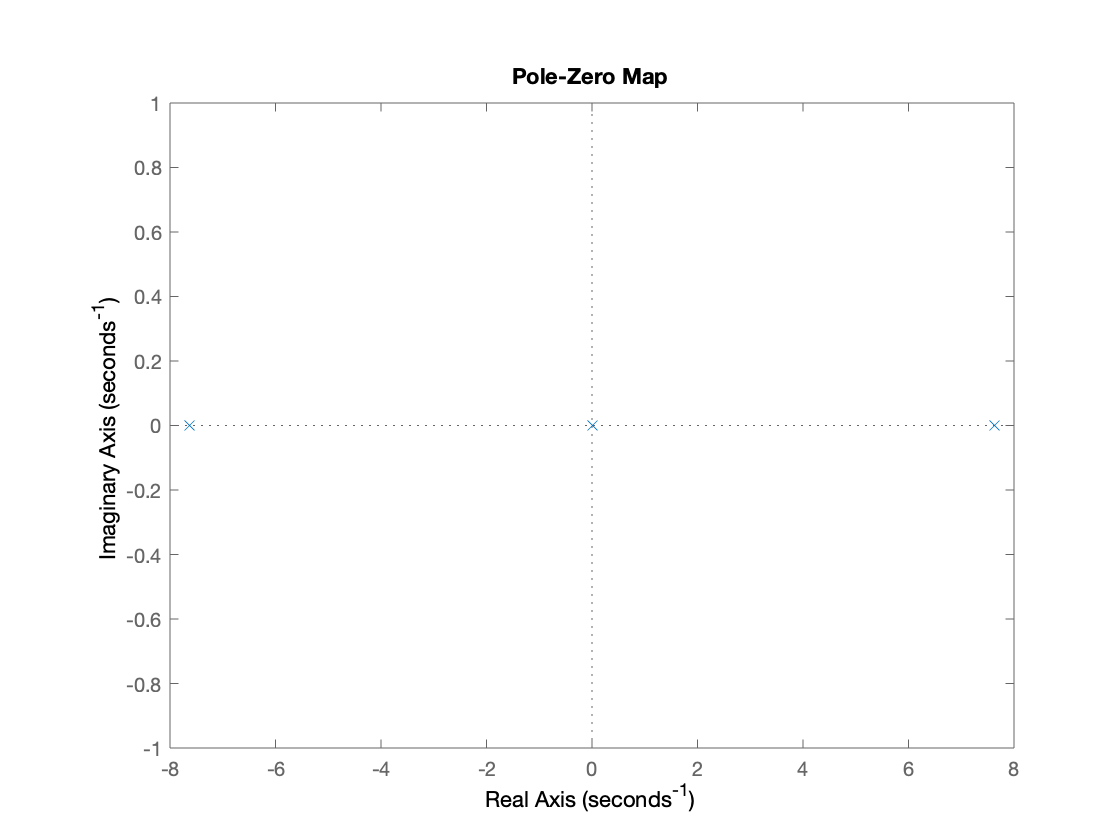

G1 = ss(A, B, C, 0);
pzplot(G1)

K = -(kg*kg*km*ke)/(mc*rg*rg*Ra);
A = [0 1 0 0 ; 0 K -mp*g/mc 0 ; 0 0 0 1 ; 0  -K/lp g/lp 0]

A =          0    1.0000         0         0
         0  -14.4899   -1.9749         0
         0         0         0    1.0000
         0   86.2495   58.3333         0


B = [0 ; (kg*km)/(mc*rg*Ra) ; 0 ; -(kg*km)/(rg*Ra*mc*lp)]

B =          0
    3.2550
         0
  -19.3751


C = [1 0 0 0 ; 0 0 1 0]

C =      1     0     0     0
     0     0     1     0


rank(obsv(A, C))

ans = 4

rank(ctrb(A, B))

ans = 4

eig(A)

ans =          0
  -15.4365
   -6.1559
    7.1024


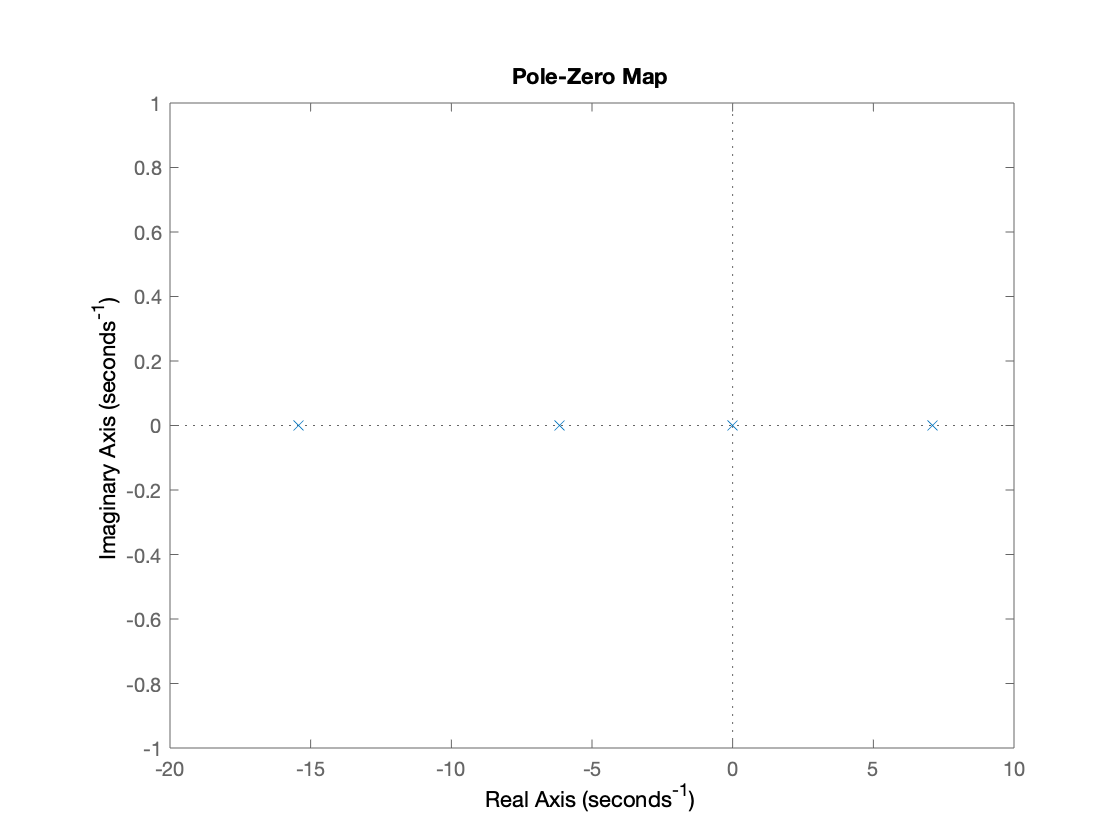

G1 = ss(A, B, C, 0);
pzplot(G1)